A = readtable("19_AS7341.csv");
B = readmatrix("19_AS7341.csv");
B = B(1:5,2:end);
B = B/32;
B = mean(B);
time = A(:,1);

channel1 = B(:,1);
channel2 = B(:,2);
channel3 = B(:,3);
channel4 = B(:,4);
channel5 = B(:,5);
channel6 = B(:,6);
channel7 = B(:,7);
channel8 = B(:,8);
clear = B(:,9);
NIR = B(:,10);

wavelengths = [410, 440, 470, 510, 550, 580, 620, 670]

wavelengths =    410   440   470   510   550   580   620   670


counts = [channel1, channel2, channel3, channel4, channel5, channel6, channel7, channel8]

counts =    18.5688   18.8438   20.3687   18.6625   18.5688   18.8438   20.3687   18.6625


ch1 = [410, channel1]

ch1 =   410.0000   18.5688


ch2 = [440, channel2]

ch2 =   440.0000   18.8438


ch3 = [470, channel3]

ch3 =   470.0000   20.3687


ch4 = [510, channel4]

ch4 =   510.0000   18.6625


ch5 = [550, channel5]

ch5 =   550.0000   18.5688


ch6 = [580, channel6]

ch6 =   580.0000   18.8438


ch7 = [620, channel7]

ch7 =   620.0000   20.3687


ch8 = [670, channel8]

ch8 =   670.0000   18.6625



spectralResponse = [ch1;ch2;ch3;ch4;ch5;ch6;ch7;ch8]

spectralResponse =   410.0000   18.5688
  440.0000   18.8438
  470.0000   20.3687
  510.0000   18.6625
  550.0000   18.5688
  580.0000   18.8438
  620.0000   20.3687
  670.0000   18.6625


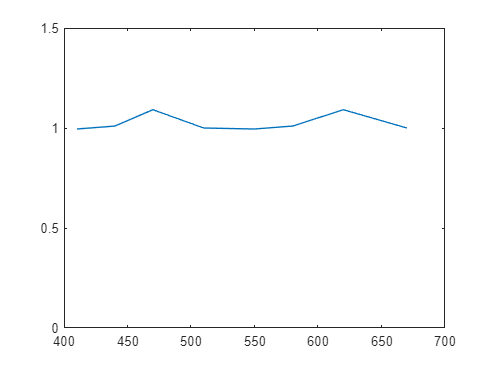

plot(wavelengths, counts/channel8)
xlim([400 700])
ylim([0 1.5])